clear all;
M_4 = 0.335; %kg
M_l = 0.065; %kg

J_l_cog = 8.74e-5; %kg/m2
J_l_piv = 4.41e-4; %kg/m2
J_4 = 1.49e-3; %kg/m2
J_4m = 3.59e-3; %kg/m2

J_motor_side = 3.9e-7 + 7.06e-8 + 2.087e-3;
%% Link Geo
L_link = 0.127; %m
L_bar = 0.13; %m
W_bar = 0.01; %m
H_bar = 0.002; %m
piv_to_cog = L_link/2;  %m

% sanity check

J_l_pivot_steiner = J_l_cog + M_l * piv_to_cog^2

J_l_pivot_steiner = 3.4950e-04


%% Motor
La = 0.18e-3;
Km = 7.68e-3; % V/(rad/s)
Ra = 2.6;


## other


beta = 0.015;


K = 7.68e-3;
J = 3.59e-3;
L = 0.18e-3;
R = 2.6;
r = 70;
J_tot = J;


gamma = (beta / J_tot)+(Ra/La)

gamma = 1.4449e+04

delta = (beta / J_tot)*(Ra/La) + Km^2 * (J_tot*La)

delta = 6.0353e+04

mu = -Km / (La * J_tot)

mu = -1.1885e+04


G_wm = tf([mu],[1 gamma delta]) %*tf([1],[1 0])


G_wm =
 
           -1.188e04
  ---------------------------
  s^2 + 1.445e04 s + 6.035e04
 
Continuous-time transfer function.
Model Properties




G_tl = G_wm*tf([1/70],[1 0])


G_tl =
 
              -169.8
  -------------------------------
  s^3 + 1.445e04 s^2 + 6.035e04 s
 
Continuous-time transfer function.
Model Properties


[C_pi,info] = pidtune(G_tl,'PI')


C_pi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = -491, Ki = -142
 
Continuous-time PI controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.3440
           PhaseMargin: 60.0000


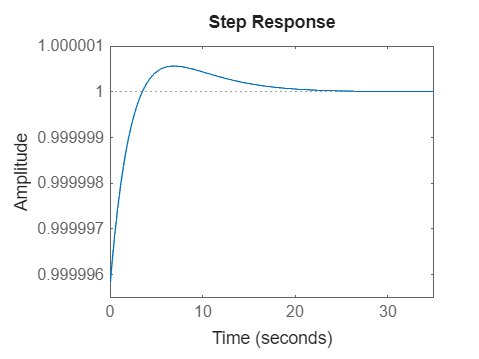

T_pi = feedback(C_pi*C_pi, 1);
step(T_pi)


zpksys = zpk(G_wm)


zpksys =
 
          -11885
  ----------------------
  (s+1.444e04) (s+4.178)
 
Continuous-time zero/pole/gain model.
Model Properties


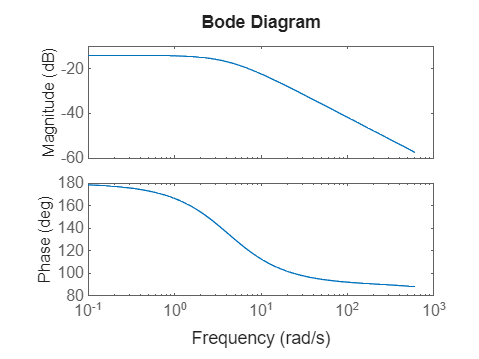

bode(G_wm,{0.1,614})

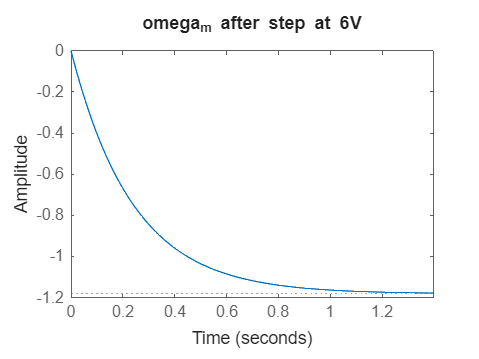


step(6*G_wm)
title("omega_m after step at 6V")

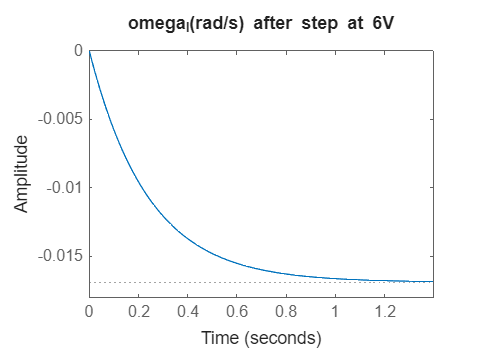

step(6*G_wm/70)
title("omega_l(rad/s) after step at 6V")

% SS

% u = Tau_dist,
%     Voltage

% y = theta_l
%     omega_m
%     i

A = [ 0, 1/r, 0;
0,-beta/J , K/J ;
0, -K/L , -R/L] ;
B = [0,0;diag([-1/J,1/L])];
C = diag([-1 1 1]);

D = zeros(3,2);



Kp = place(A,B,[-40,-80,-20]);


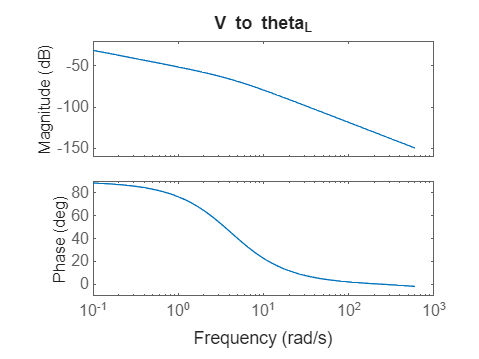


Gss = ss(A,B,C,D);
bode( Gss(1,2),{0.1,614})
title("V to theta_L")

zpk( Gss(1,2))


ans =
 
          -169.78
  ------------------------
  s (s+4.185) (s+1.444e04)
 
Continuous-time zero/pole/gain model.
Model Properties


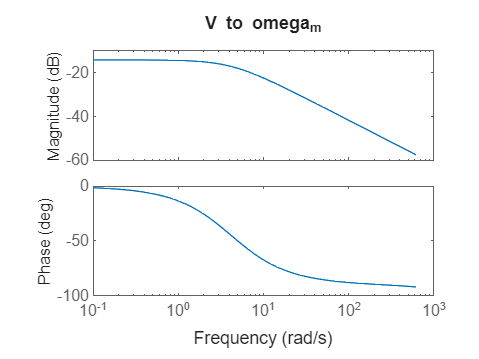






bode( Gss(2,2),{0.1,614})
title("V to omega_m")

zpk( Gss(2,2))


ans =
 
          11885
  ----------------------
  (s+4.185) (s+1.444e04)
 
Continuous-time zero/pole/gain model.
Model Properties


Gvq =  Gss(1,2);
Cont = pidtune(Gvq,'PID')


Cont =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -3.51e+03, Ki = -4.19e+03, Kd = -738
 
Continuous-time PID controller in parallel form.
Model Properties


Cpv = pid(6.2e+03,0,1.49e+03)


Cpv =
 
             
  Kp + Kd * s
             

  with Kp = 6.2e+03, Kd = 1.49e+03
 
Continuous-time PD controller in parallel form.
Model Properties


% pidTuner(Gvq,Cont)

